# リーマンゼータ関数と作用素の固有値


$$Tr(x^N\partial ^N(-1)^\theta )=\frac12N!\left(-\frac12\right)^N$$


$S_{II}:$第二種Stirling数


$$Tr(\theta ^n(-1)^\theta )=0^n+(2^{1+n}-1)\zeta (-n)=\frac12\sum_{k=0}^nS_{II}(n,k)k!\left(-\frac12\right)^k$$



$$Tr(\theta ^nz^\theta )=0^n+\Psi_{-n}(z)=\frac1{1-z}\sum_{k=0}^nS_{II}(n,k)k!\left(\frac{z}{1-z}\right)^k\qquad (n\in \mathbb N)$$


N=10;
e1=zeros(1,N);
for n=0:length(e1)
    ii=sym(0:n);
    e1(n+1)=(factorial(ii).*(-1/2).^ii)/2*stirling2(n,ii,'sym').';  
end

関数または変数 'stirling2' が認識されません。

n=0:N;
[e1;(2.^n*2-1).*zeta0(-n);polylog(-n,-1)]

N=10;
z=2;
e1=zeros(1,N);
for n=0:length(e1)
    ii=sym(0:n);
    e1(n+1)=(factorial(ii).*(z/(1-z)).^ii)*stirling2(n,ii,'double').'/(1-z);  
end
n=0:N;
[e1;polylog(-n,z)]


$$\sum_k(S_I(m,k))(S_{II}(k,m)(-1)^{k+m})=\delta_{mn}$$


stirling1(0:3,0:3,"double")*((-1).^((0:3)'+(0:3)).*stirling2(0:3,0:3,"double"))


$$\binom{x}{n}=\frac1{n!}\sum_{k=0}^nS_{I}(n,k)(-1)^{n+k}}x^{n-k}$$


N=4;
ii=0:N;
figure
fplot(@(x)gamma(x+1)./gamma(x-N+1)/factorial(N))
hold on
fplot(@(x)arrayfun(@(y)(-1).^ii.*y.^ii*stirling1(N,ii).'/factorial(N)*(-1)^N,x))

## Abaloneの計算の最終ステップ


$$\left[\begin{array}{c}
n\\m
\end{array}\right]_{\exp \hbar}=\binom nm\left(1+\frac{\hbar^2}{6}m(n+1)(n-m)\left(1+\frac{\hbar^2}{60}((5m - 2) n^2 - (m - 1)(5m - 2) n - {7} m^2)\right)\right)+o(\hbar^6)$$



$$Z\left({\mathbb{S}}^3 \;;U_{\hbar } \left({\textrm{sl}}_2^+ \right)\right)=\textrm{Tr}\left(\sum_{n\ge 0} q^{-n^2 +4n+\left(n-2\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \right)=^? q^2$$



$$\textrm{Tr}\left(\sum_{n\ge 0} q^{3n^2 +5n-\left(n+2\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \right)=^? q^{-1}$$



$$\sum_{n\ge 0} q^{-n^2 +4n+\left(n-2\right)\theta } {\left\lbrack \begin{array}{c}
\theta_z \\
n
\end{array}\right\rbrack }_q \cdot \frac{1}{1-z}$$



$$\textrm{Tr}\left(\sum_{n\ge 0} q^{3n^2 +\left(4-u\right)n-\left(n+2\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \right)=^? q^u$$



$$\textrm{Tr}\left(\sum_{n\ge 0} q^{-n^2 +\left(2+u\right)n+\left(n-u\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \right)=\sum_{n\ge 0} q^{-n^2 +\left(2+u\right)n+\left(n-u\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \frac{1}{1-y}|_{y=1} =^? q^u$$



$$\textrm{Tr}\left(_3 \phi_0 \left\lbrack \begin{array}{cc}
 & \\
 & 
\end{array}\right\rbrack \right)$$



$$\textrm{sgn}\left(1-a\right)=\left\lbrace \begin{array}{ll}
-１ & \left(a>1\right)\\
1 & \left(a<1\right)
\end{array}\right.$$



$$$\mathrm{Tr}\left({}_3 \phi_0 \left\lbrack \begin{array}{cc}
 0,0,q^{-\theta} \\
 -
\end{array};q;q^{-2-t}\right\rbrack q^{\theta} \right)=q^t$$$


を計算する必要がある

z=1;
syms n1 th hb u1
e11=exp(hb*(-n1^2+(2+u1)*n1+(-u1+n1)*th))*(1+hb^2*n1*(th+1)*(th-n1)/6*(1+hb^2*((5*n1-2)*(th-n1+1)*th-7*n1^2)/60));
e1=taylor(e11,hb,Order=6);%hbar展開
% e1=1+hb*(3*n1^2+5*n1-(n1+2)*th);
e2=fliplr(coeffs(e1,hb,'all'));%hb各項
r1=length(e2);%hb次数
e5=e2;%hbについての作用素の展開
e7=e2;%hbのついてのtraceの展開
for i1=1:r1%hb各項で計算
    e4=fliplr(coeffs(e2(i1),n1,'all'));%n1:作用素の和
    r2=0:length(e4)-1;
    e6=e4*stirling2(r2,r2);
    e6=e6.*(z/(1+z)).^r2*(factorial(r2).*binom(th,r2)).';
    e5(i1)=e6;
    e8=fliplr(coeffs(e6,th,'all'));
    e7(i1)=sign(-z)*sum(polylog0(-(0:length(e8)-1),1+z).*e8);

１end
SI(e5)
SI(e7)

SI(e1)

$$ans = \begin{array}{l} \left({\sigma_{1}}^{4}\,\left(\frac{\mathrm{th}\,\left(n_{1}-u_{1}\right)}{120}+\frac{n_{1}\,\left(u_{1}+2\right)}{120}-\frac{{n_{1}}^{2}}{120}\right)+\frac{n_{1}\,\sigma_{2}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)\,\sigma_{1}}{6}-\frac{n_{1}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)\,{\sigma_{1}}^{2}\,\sigma_{3}}{6}\right)\,{\mathrm{hb}}^{5}+\left({\sigma_{1}}^{3}\,\left(\frac{\mathrm{th}\,\left(n_{1}-u_{1}\right)}{24}+\frac{n_{1}\,\left(u_{1}+2\right)}{24}-\frac{{n_{1}}^{2}}{24}\right)+\frac{n_{1}\,\sigma_{2}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)}{6}-\frac{n_{1}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)\,\sigma_{1}\,\sigma_{4}}{6}\right)\,{\mathrm{hb}}^{4}+\left({\sigma_{1}}^{2}\,\sigma_{3}-\frac{n_{1}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)\,\sigma_{1}}{6}\right)\,{\mathrm{hb}}^{3}+\left(\sigma_{1}\,\sigma_{4}-\frac{n_{1}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)}{6}\right)\,{\mathrm{hb}}^{2}+\sigma_{1}\,\mathrm{hb}+1\\ \mathrm{where}\\ \sigma_{1}=\mathrm{th}\,\left(n_{1}-u_{1}\right)+n_{1}\,\left(u_{1}+2\right)-{n_{1}}^{2}\\ \sigma_{2}=\frac{7\,{n_{1}}^{2}}{60}-\frac{\mathrm{th}\,\left(5\,n_{1}-2\right)\,\left(\mathrm{th}-n_{1}+1\right)}{60}\\ \sigma_{3}=\frac{\mathrm{th}\,\left(n_{1}-u_{1}\right)}{6}+\frac{n_{1}\,\left(u_{1}+2\right)}{6}-\frac{{n_{1}}^{2}}{6}\\ \sigma_{4}=\frac{\mathrm{th}\,\left(n_{1}-u_{1}\right)}{2}+\frac{n_{1}\,\left(u_{1}+2\right)}{2}-\frac{{n_{1}}^{2}}{2} \end{array}$$

syms z
qN=qNumS();
expr=0;
for ii=0:4
    expr=expr+SI(qN.q^(3*ii^2+5*ii-(ii+2)*z)*qN.binomial(z,ii));
end
factor(SI(expr)).'

$$ans = \begin{array}{l} \left(\begin{array}{c} q^{8\,z}+q^{84}-q^{8\,z}\,q^{2}-q^{8\,z}\,q^{4}+q^{6\,z}\,q^{9}-q^{8\,z}\,q^{9}+2\,q^{8\,z}\,q^{10}-q^{6\,z}\,q^{13}-q^{6\,z}\,q^{15}+q^{8\,z}\,q^{13}-q^{6\,z}\,q^{17}+q^{8\,z}\,q^{15}-q^{8\,z}\,q^{16}+q^{6\,z}\,q^{19}+q^{8\,z}\,q^{17}-q^{8\,z}\,q^{18}+q^{6\,z}\,q^{21}-q^{8\,z}\,q^{19}+q^{8\,z}\,q^{20}+q^{6\,z}\,q^{23}-q^{8\,z}\,q^{21}+q^{4\,z}\,q^{26}-q^{6\,z}\,q^{24}-q^{8\,z}\,q^{23}-q^{6\,z}\,q^{26}+q^{8\,z}\,q^{24}-q^{6\,z}\,q^{27}+q^{8\,z}\,q^{27}-q^{4\,z}\,q^{32}+q^{6\,z}\,q^{30}-q^{4\,z}\,q^{34}+2\,q^{6\,z}\,q^{32}-q^{8\,z}\,q^{30}+q^{6\,z}\,q^{34}-q^{8\,z}\,q^{32}+q^{4\,z}\,q^{40}-q^{6\,z}\,q^{38}-q^{6\,z}\,q^{40}+q^{8\,z}\,q^{38}-q^{4\,z}\,q^{47}+q^{6\,z}\,q^{45}+q^{2\,z}\,q^{51}-q^{4\,z}\,q^{49}+q^{6\,z}\,q^{47}-q^{8\,z}\,q^{45}-q^{4\,z}\,q^{51}+q^{6\,z}\,q^{49}+q^{4\,z}\,q^{55}-q^{6\,z}\,q^{53}-q^{2\,z}\,q^{59}+q^{4\,z}\,q^{57}-q^{6\,z}\,q^{55}+q^{8\,z}\,q^{53}+q^{4\,z}\,q^{59}-q^{6\,z}\,q^{57}+q^{4\,z}\,q^{74}-q^{6\,z}\,q^{72}-q^{2\,z}\,q^{78}+q^{4\,z}\,q^{76}-q^{6\,z}\,q^{74}+q^{8\,z}\,q^{72}-q^{2\,z}\,q^{80}+2\,q^{4\,z}\,q^{78}-q^{6\,z}\,q^{76}-q^{2\,z}\,q^{82}+q^{4\,z}\,q^{80}-q^{6\,z}\,q^{78}-q^{2\,z}\,q^{84}+q^{4\,z}\,q^{82}\\ \sigma_{1}\\ \sigma_{1}\\ \sigma_{1}\\ \sigma_{1}\\ \sigma_{1}\\ \frac{1}{q^{4}+1}\\ \frac{1}{q^{2}-q+1}\\ \frac{1}{q^{2}+q+1}\\ \sigma_{2}\\ \sigma_{2}\\ \frac{1}{q-1}\\ \frac{1}{q-1}\\ \frac{1}{q-1}\\ \frac{1}{q-1}\\ \frac{1}{q+1}\\ \frac{1}{q+1}\\ \frac{1}{q+1}\\ \frac{1}{q+1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{q^{2\,z}}\\ \sigma_{2}=\frac{1}{q^{2}+1} \end{array}$$

syms z
cf=fliplr(coeffs(z^3+2*z^2,'All'));
cf=stirling2(0:length(cf)-1,0:length(cf)-1).'*cf.'
SI(binom(z,3)*6+5*binom(z,2)*2+3*binom(z,1))

expr=0;
for n=0:50
    expr=expr+log(2)^n*zeta0(-n)/factorial(n);
end
expr

expr = 0.4427


$$\sum_{n\ge 0} q^{-n^2 +4n+\left(n-2\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \cdot \frac{1}{1-z}=\sum_{n\ge 0} q^{4n-2\theta } {{\left({{\theta }\atop{n}}\right)}}_{q^2 } \cdot \frac{1}{1-z}=\sum_{n\ge 0} q^{4n-2\theta } \frac{z^n }{{\left(z;q^2 \right)}_{n+1} }=\sum_{n\ge 0} \frac{{q^{2n} z}^n }{{\left(q^{-2} z;q^2 \right)}_{n+1} }=$$

$$\frac{1}{1-q^{-2} z}\sum_{n\ge 0} \frac{q^{2n} }{{\left(z^{-1} ;q^{-2} \right)}_n }q^{-2{\left({{n}\atop{2}}\right)}} =\frac{1}{1-q^{-2} z}{}_1{\phi }_1\left\lbrack \begin{array}{cc}
q^{-2}  & {;q}^{-2} ;q^2 \\
z^{-1}  & 
\end{array}\right\rbrack =$$


syms z
syms q
expr=sym(0);
for n=0:3
f=1/(1-z);
g=f;
for ii=0:n-1
f=(q^-ii*subs(f,z,q*z)-f)/(q^(n-ii)-1);
g=g*z/(1-q^(1+ii)*z);
end
expr(1,n+1)=f;
expr(2,n+1)=g;
% f=subs(f,z,z/q)*q^(2*n);
% expr=expr+(f);
end
SI(expr(1,:))

$$ans = \begin{array}{l} \left(\begin{array}{cccc} -\frac{1}{z-1} & \frac{z}{\left(q\,z-1\right)\,\left(z-1\right)} & -\frac{z^{2}}{\left(z-1\right)\,\left(\sigma_{1}-q^{2}\,z-q\,z+1\right)} & -\frac{z^{3}}{\left(z-1\right)\,\left(-q^{6}\,z^{3}+q^{5}\,z^{2}+q^{4}\,z^{2}+\sigma_{1}-q^{3}\,z-q^{2}\,z-q\,z+1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=q^{3}\,z^{2} \end{array}$$

% arrayfun(@(x)disp(factor(x)),expr(1,:))
SI(expr(1,:)./expr(2,:))

$$ans = \left(\begin{array}{cccc} 1 & 1 & 1 & 1 \end{array}\right)$$

close all
a=.95;
double(subs(subs(f,q,a),z,1.048))

ans = 1.7299e+05

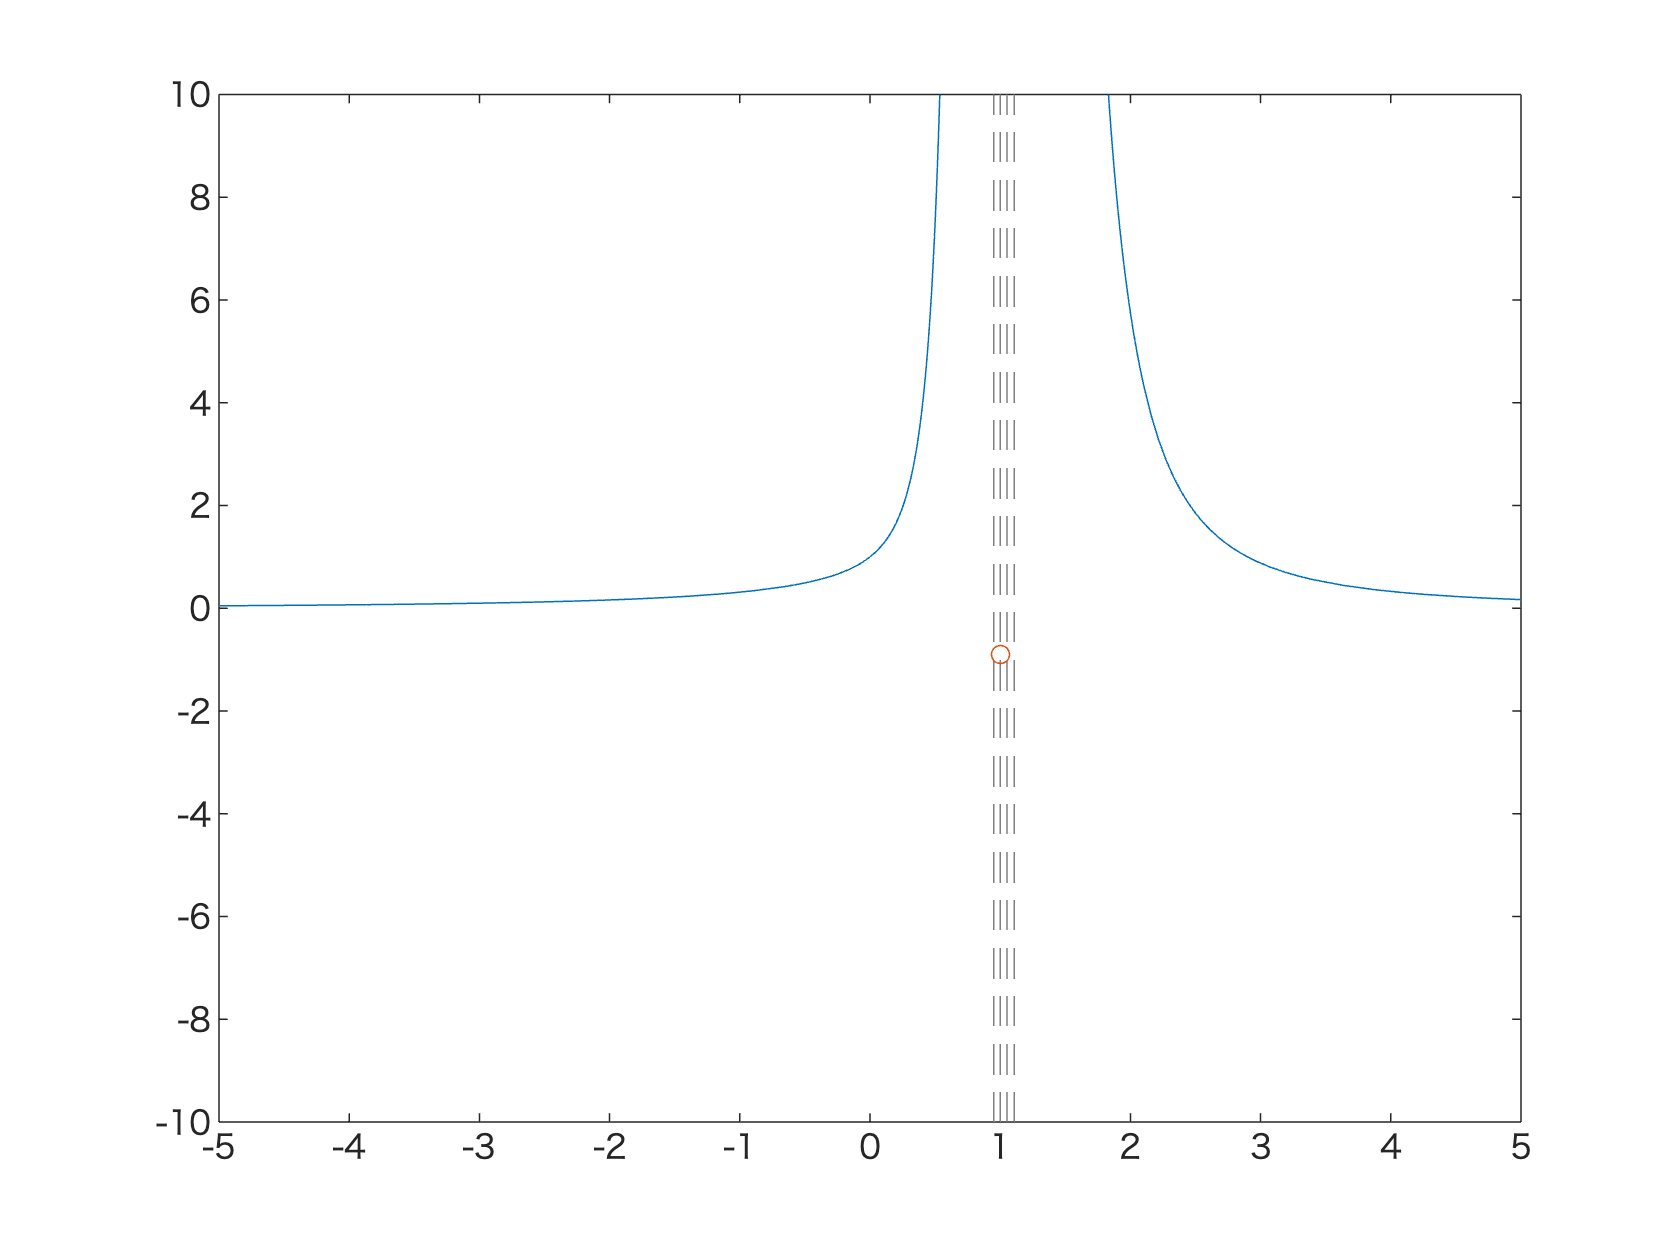

figure(1)
f=subs(expr,q,a);
fplot(f)
hold on 
scatter(1,-a^2)
% for ii=1:6
%     expr=expr*(1-q^(2*ii)*z);
% end
% f=subs(expr,q,a);
% fplot(f)
ylim([-10 10])

% SI((1/(1-q*z)-1/(1-z/q))/(q-q^-1))

n=5;
ii=0:n;
a=-1;
b=2;
sum(binom(n,ii).*polylog0(-2*n+ii,a).*b.^ii)

ans = -0.5000


syms n1 th hb ep

ord=5;
e12=(1+hb^2*n1*(th+1)*(th-n1)/6*(1+hb^2*((5*n1-2)*(th-n1+1)*th-7*n1^2)/60));
e11=exp(hb*(2*n1+th*n1-2*th))*subs(e12,th,n1+th);% binom(th,n)->binom(th+n,n)
e1=taylor(e11,hb,Order=ord+1);
% e1=1+hb*(3*n1^2+5*n1-(n1+2)*th);
e2=fliplr(coeffs(e1,hb,'all'));
r1=length(e2);% hb展開係数の配列の長さ
e5=e2;
e7=e2;
for i1=1:r1
    e4=fliplr(coeffs(e2(i1),n1,'all'));
    r2=0:length(e4)-1;
    e6=e4*stirling2(r2,r2);% n^m展開係数をn!/(n-m)!展開係数に
    e6=e6.*((1-ep)/ep).^r2*(factorial(r2).*binom(-th-1,r2).*(-1).^r2).';
    e5(i1)=e6;
    e8=fliplr(coeffs(e6,th,'all'));
    e7(i1)=1/ep*sum(polylog0(-(0:length(e8)-1),ep^-1).*e8);

end
SI(e5)

SI(-e7*(1-ep))

$$ans = \left(\begin{array}{cccccc} 1 & -\frac{2\,\mathrm{ep}+2}{\mathrm{ep}-1} & \frac{2\,{\mathrm{ep}}^{2}+20\,\mathrm{ep}+2}{{\left(\mathrm{ep}-1\right)}^{2}} & -\frac{4\,{\mathrm{ep}}^{3}+212\,{\mathrm{ep}}^{2}+356\,\mathrm{ep}+4}{3\,{\left(\mathrm{ep}-1\right)}^{3}} & \frac{2\,{\mathrm{ep}}^{4}+472\,{\mathrm{ep}}^{3}+3084\,{\mathrm{ep}}^{2}+2200\,\mathrm{ep}+2}{3\,{\left(\mathrm{ep}-1\right)}^{4}} & -\frac{4\,{\mathrm{ep}}^{5}+3948\,{\mathrm{ep}}^{4}+72608\,{\mathrm{ep}}^{3}+188528\,{\mathrm{ep}}^{2}+80508\,\mathrm{ep}+4}{15\,{\left(\mathrm{ep}-1\right)}^{5}} \end{array}\right)$$

-subs(SI(e7),ep,0).*factorial(0:ord)

$$ans = \left(\begin{array}{cccccc} 1 & 2 & 4 & 8 & 16 & 32 \end{array}\right)$$

-subs(SI(e7),ep,0).*factorial(0:ord)

$$ans = \left(\begin{array}{cccccc} 1 & 2 & 4 & 8 & 16 & 32 \end{array}\right)$$

$\left(\begin{array}{cccccc}

1 & -\frac{2\,\mathrm{ep}+2}{\mathrm{ep}-1} & \frac{2\,{\mathrm{ep}}^2 +20\,\mathrm{ep}+2}{{{\left(\mathrm{ep}-1\right)}}^2 } & -\frac{4\,{\mathrm{ep}}^3 +212\,{\mathrm{ep}}^2 +356\,\mathrm{ep}+4}{3\,{{\left(\mathrm{ep}-1\right)}}^3 } & \frac{2\,{\mathrm{ep}}^4 +472\,{\mathrm{ep}}^3 +3084\,{\mathrm{ep}}^2 +2200\,\mathrm{ep}+2}{3\,{{\left(\mathrm{ep}-1\right)}}^4 } & -\frac{4\,{\mathrm{ep}}^5 +3948\,{\mathrm{ep}}^4 +72608\,{\mathrm{ep}}^3 +188528\,{\mathrm{ep}}^2 +80508\,\mathrm{ep}+4}{15\,{{\left(\mathrm{ep}-1\right)}}^5 }

\end{array}\right)$

syms u
v=u/(1-u);
f=1/v*(1+u)/(1-u)^2+2/v-(3-5*u)/u/(1-u)

$$f = -\frac{2\,\left(u-1\right)}{u}-\frac{u+1}{u\,\left(u-1\right)}-\frac{5\,u-3}{u\,\left(u-1\right)}$$

simplify(f)

$$ans = -\frac{2\,\left(u+1\right)}{u-1}$$

taylor(expand(SI(e5(3))),th)

$$ans = \mathrm{th}\,\left(\frac{31}{3\,{\mathrm{ep}}^{2}}-\frac{61}{3\,\mathrm{ep}}+10\right)-\frac{6}{\mathrm{ep}}+\frac{4}{{\mathrm{ep}}^{2}}+{\mathrm{th}}^{4}\,\left(\frac{1}{2\,{\mathrm{ep}}^{2}}-\frac{1}{\mathrm{ep}}+\frac{1}{2}\right)+{\mathrm{th}}^{3}\,\left(\frac{11}{3\,{\mathrm{ep}}^{2}}-\frac{26}{3\,\mathrm{ep}}+5\right)+{\mathrm{th}}^{2}\,\left(\frac{19}{2\,{\mathrm{ep}}^{2}}-\frac{22}{\mathrm{ep}}+\frac{29}{2}\right)+2$$